function [centroids_L1] = updateCentroidsL1(X, idx, k, lambda)
    % X - data matrix (each row is a data point)
    % idx - index of data points assigned to clusters
    % k - number of clusters
    % lambda - L1 regularization parameter
    
    centroids_L1 = zeros(k, size(X, 2));  % Initialize centroids
    
    for j = 1:k
        % Find the points assigned to cluster j
        pointsInCluster = X(idx == j, :);
        
        % Calculate the centroid for cluster j
        centroid = mean(pointsInCluster, 1);
        
        % Apply L1 regularization to the centroid (shrinkage)
        centroids_L1(j, :) = centroid - lambda * sign(centroid);
    end
end

% Regularization parameter lambda for L1 penalty
lambda_L1 = 0.1;  % Set your L1 regularization parameter

% List of benign image names
benignImages = {'ISIC_0000001.jpg', 'ISIC_0000017.jpg', 'ISIC_0000028.jpg', 'ISIC_0000062.jpg', 'ISIC_0000065.jpg', 'ISIC_0000130.jpg', 'ISIC_0000240.jpg', 'ISIC_0000261.jpg', 'ISIC_0000265.jpg', 'ISIC_0000381.jpg', 'ISIC_0000383.jpg', 'ISIC_0000384.jpg', 'ISIC_0000386.jpg', 'ISIC_0000396.jpg', 'ISIC_0000397.jpg', 'ISIC_0000409.jpg', 'ISIC_0000416.jpg', 'ISIC_0000427.jpg', 'ISIC_0000431.jpg', 'ISIC_0000455.jpg', 'ISIC_0000460.jpg', 'ISIC_0000483.jpg', 'ISIC_0000488.jpg', 'ISIC_0000489.jpg', 'ISIC_0000495.jpg', 'ISIC_0000507.jpg', 'ISIC_0009871.jpg', 'ISIC_0009883.jpg', 'ISIC_0009884.jpg', 'ISIC_0009914.jpg'};  

% List of malignant image names
malignantImages = {'ISIC_0000029.jpg', 'ISIC_0000054.jpg', 'ISIC_0000152.jpg', 'ISIC_0000390.jpg', 'ISIC_0001106.jpg', 'ISIC_0009868.jpg', 'ISIC_0009905.jpg', 'ISIC_0009950.jpg', 'ISIC_0009960.jpg', 'ISIC_0009971.jpg', 'ISIC_0010036.jpg', 'ISIC_0010080.jpg', 'ISIC_0010225.jpg', 'ISIC_0010241.jpg', 'ISIC_0010251.jpg', 'ISIC_0010265.jpg', 'ISIC_0010321.jpg', 'ISIC_0010350.jpg', 'ISIC_0010358.jpg', 'ISIC_0010364.jpg', 'ISIC_0010372.jpg', 'ISIC_0010380.jpg', 'ISIC_0010466.jpg', 'ISIC_0010468.jpg', 'ISIC_0010476.jpg', 'ISIC_0010576.jpg', 'ISIC_0010852.jpg', 'ISIC_0010860.jpg', 'ISIC_0011118.jpg', 'ISIC_0011135.jpg', 'ISIC_0011137.jpg', 'ISIC_0011140.jpg', 'ISIC_0011163.jpg', 'ISIC_0011169.jpg', 'ISIC_0011366.jpg'};  

% Combine the image names into one list
imageNames = [benignImages, malignantImages];  

% Create a corresponding label list
labels_L1 = [repmat({'Benign'}, 1, length(benignImages)), repmat({'Malignant'}, 1, length(malignantImages))];

% Extract features for clustering (ensure 'reducedFeatureTable' is defined and contains features)
featuresMatrix_L1 = table2array(reducedFeatureTable(:, 2:end)); 

% Normalize features
normalizedFeatures_L1 = zscore(featuresMatrix_L1);

% Create an empty cell array to store the results
results_L1 = cell(size(normalizedFeatures_L1, 1), 3);

% Pre-allocate the predictions cell array
predictions_L1 = cell(size(normalizedFeatures, 1), 1);  % Initialize predictions as a cell array of the appropriate size

% Store image names, true labels, and predictions
for i = 1:size(normalizedFeatures_L1, 1)
    
    % Create training set (all images except the ith image)
    X_train_L1 = normalizedFeatures_L1([1:i-1, i+1:end], :);  % Exclude the ith row (observation)
    labels_train_L1 = labels_L1([1:i-1, i+1:end]);  % Corresponding labels for training data
    
    % Create test set (the ith image)
    X_test_L1 = normalizedFeatures_L1(i, :);  % The ith row (observation) for testing
    label_test_L1 = labels_L1(i);  % The label for the ith image

    % Train k-means with 2 clusters
    k = 2;  % Number of clusters
    idx_train_L1 = kmeans(X_train_L1, k, 'Replicates', 10, 'Start', 'plus');
    
    % Get cluster centers for prediction
    cluster_centers_L1 = zeros(k, size(normalizedFeatures_L1, 2));  % To store cluster centers
    for j = 1:k
        cluster_centers_L1(j, :) = mean(X_train_L1(idx_train_L1 == j, :), 1);  % Cluster center for each cluster
    end

    % Apply L1 regularization to the centroids
    centroids_L1 = updateCentroidsL1(X_train_L1, idx_train_L1, k, lambda_L1);

    % Calculate distance from the test image to each cluster center
    distances_L1 = sum((centroids_L1 - X_test_L1).^2, 2);  % Euclidean distance squared
    
    % Predict the label based on the nearest cluster center
    [~, predictedCluster_L1] = min(distances_L1);
    
    % Assign predicted label based on the cluster number
    if predictedCluster_L1 == 1
        predictions_L1{i} = 'Benign';  % Assuming cluster 1 is benign
    else
        predictions_L1{i} = 'Malignant';  % Assuming cluster 2 is malignant
    end
    
    % Store the data in the results array
    results_L1{i, 1} = imageNames{i};
    results_L1{i, 2} = label_test_L1{1};
    results_L1{i, 3} = predictions_L1{i};
end

% Convert the results array to a table for better visualization
resultsTable_L1 = cell2table(results_L1, 'VariableNames', {'Image', 'TrueLabel_L1', 'PredictedLabel_L1'});

% Display the table
disp(resultsTable_L1);

           Image            TrueLabel_L1     PredictedLabel_L1
    ____________________    _____________    _________________

    {'ISIC_0000001.jpg'}    {'Benign'   }      {'Malignant'}  
    {'ISIC_0000017.jpg'}    {'Benign'   }      {'Malignant'}  
    {'ISIC_0000028.jpg'}    {'Benign'   }      {'Malignant'}  
    {'ISIC_0000062.jpg'}    {'Benign'   }      {'Benign'   }  
    {'ISIC_0000065.jpg'}    {'Benign'   }      {'Malignant'}  
    {'ISIC_0000130.jpg'}    {'Benign'   }      {'Malignant'}  
    {'ISIC_0000240.jpg'}    {'Benign'   }      {'Malignant'}  
    {'ISIC_0000261.jpg'}    {'Benign'   }      {'Benign'   }  
    {'ISIC_0000265.jpg'}    {'Benign'   }      {'Malignant'}  
    {'ISIC_0000381.jpg'}    {'Benign'   }      {'Benign'   }  
    {'ISIC_0000383.jpg'}    {'Benign'   }      {'Malignant'}  
    {'ISIC_0000384.jpg'}    {'Benign'   }      {'Malignant'}  
    {'ISIC_0000


% After the loop finishes, calculate the error rate
% Compare predictions with the actual labels
labels_L1 = labels_L1';
numIncorrect_L1 = sum(~strcmp(predictions_L1, labels_L1));  % Count mismatches
numTotal_L1 = length(labels_L1);  % Total number of images

% Calculate the error rate
errorRate_L1 = numIncorrect_L1 / numTotal_L1;

% Display the error rate
fprintf('L1 Test Error Rate: %.2f%%\n', errorRate_L1 * 100);

L1 Test Error Rate: 50.77%


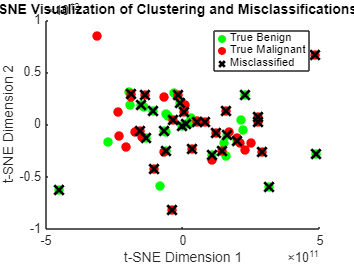

% Convert predictions{} to a column vector
predictedLabels_L1 = predictions_L1(:);  % Convert cell array to column vector

% Perform t-SNE to reduce dimensionality to 2D
reducedFeatures2D_L1 = tsne(normalizedFeatures_L1, 'Perplexity', 30, 'Exaggeration', 12);

% Prepare data for plotting
trueLabels_L1 = labels(:);  % Ensure labels are in column vector form
benignIdx_L1 = strcmp(trueLabels_L1, 'Benign');
malignantIdx_L1 = strcmp(trueLabels_L1, 'Malignant');

% Plot true labels
figure;
scatter(reducedFeatures2D_L1(benignIdx_L1, 1), reducedFeatures2D_L1(benignIdx_L1, 2), 50, 'g', 'filled', 'DisplayName', 'True Benign');
hold on;
scatter(reducedFeatures2D_L1(malignantIdx_L1, 1), reducedFeatures2D_L1(malignantIdx_L1, 2), 50, 'r', 'filled', 'DisplayName', 'True Malignant');

% Highlight misclassified points
mismatchIdx_L1 = ~strcmp(trueLabels_L1, predictedLabels_L1);
scatter(reducedFeatures2D_L1(mismatchIdx_L1, 1), reducedFeatures2D_L1(mismatchIdx_L1, 2), 100, 'kx', 'LineWidth', 2, 'DisplayName', 'Misclassified');

% Add legend and title
legend;
title('t-SNE Visualization of Clustering and Misclassifications L1');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
hold off;